Promentilla, Jose Mikhael Uriel

Dela Torre, Alexczar

# DSP MP4

## Convolution [Bag X-Ray]

### Notes on #1:

Testing was done on conv2 function. Based from the testing, the desired implementation was different from the conv2 function. Therefore, the personal implementation of the 3x3 PSF, was done as the function myconv. The difference between the outputs of the 2 functions can be observed from the “cameraman” image. Due to the flipping operations of the conv2 function, the white outline of the man is missed. Meanwhile this problem was solved in the implemented function myconv. Thus, the following tasks was done on myconv.

## Q1:

Question: What is the value of your threshold in part (d)? How did you obtain this threshold? Explain briefly.

Threshold value = 10.8048121015696

Specified limit = 3.

#### Brief Process:

The new method is known as the Automatic Thresholding method[1]. The idea behind the method is to keep adjusting the threshold such that the image is split into the foreground and the background. The algorithm is as follows:

#### Automatic Thresholding Algorithm [2]:

1. Select initial threshold value, typically the mean 8-bit value of the original image. 

2. Divide the original image into two portions; 

    1. Pixel values that are less than or equal to the threshold; background 

    2. Pixel values greater than the threshold; foreground 

3. Find the average mean values of the two new images 

4. Calculate the new threshold by averaging the two means. 

5. If the difference between the previous threshold value and the new threshold value are below a specified limit, you are finished. Otherwise apply the new threshold to the original image keep trying. 

No histogram equalization was done as it was found to give unsatisfactory results compared to doing one. 

#### Entire Process: 

The method requires a hyperparameter that is specified limit for the threshold difference. This hyperparameter was gained by setting the value to 1, then incrementing it until a satisfactory result was gained. The specified limit the best at 3. 

Initially, attempted thresholding was done by doing histogram equalization and thresholding through thresholding methods in the previous MP3.

#### Previous Thresholding Methods:

- Set the threshold when the cumulative frequency exceeds half the total frequency of an intensity in the image

- Getting the 2 peaks of the histogram and setting the threshold as the average of the peaks.

But observed unsatisfactory results in the image.

Therefore, a new thresholding method was implemented.

The new method is known as the Automatic Thresholding method[1]. The idea behind the method is to keep adjusting the threshold such that the image is split into the foreground and the background. The algorithm is as follows:

#### Automatic Thresholding Algorithm [2]:

1. Select initial threshold value, typically the mean 8-bit value of the original image. 

2. Divide the original image into two portions; 

    1. Pixel values that are less than or equal to the threshold; background 

    2. Pixel values greater than the threshold; foreground 

3. Find the average mean values of the two new images 

4. Calculate the new threshold by averaging the two means. 

5. If the difference between the previous threshold value and the new threshold value are below a specified limit, you are finished. Otherwise apply the new threshold to the original image keep trying.

The method requires a hyperparameter that is specified limit for the threshold difference. This hyperparameter was gained by setting the value to 1, then incrementing it until a satisfactory result was gained. The specified limit the best at 3.

Automatic thresholding was also experimented with histogram equalization. But histogram equalization was incompatible with automatic thresholding as it pushed most values into fewer bins, making the automatic thresholding suboptimal and giving bad results such as a completely white image.

[1] Umbaugh, S. E. (2017). Digital Image Processing and Analysis with MATLAB and CVIPtools, Third Edition.

[2] Retrieved from [https://en.wikipedia.org/wiki/Thresholding_(image_processing](https://en.wikipedia.org/wiki/Thresholding_(image_processing))

% test images
testimg1 = [1 2 3
           4 5 6
           7 8 9];
       
testimg2 = [9 8 7
            6 5 4
            3 2 1];

iden = [0 0 0
        0 1 0
        0 0 0];   
    
shiftsub = [0 0 0
            0 1 0
            0 0 -1];
       
% CAMERAMAN
img = imread('cameraman.png');
img = rgb2gray(img);

figure('Name','Cameraman Shift and Subtract Image','NumberTitle','off');
subplot(1,3,1);
imshow(img);

title('Original Image')

convimg1 = uint8(conv2(img, shiftsub));
subplot(1,3,2);
imshow(convimg1);

title('Conv2 Image')

convimg2 = uint8(myconv(img, shiftsub));
subplot(1,3,3);
imshow(convimg2);

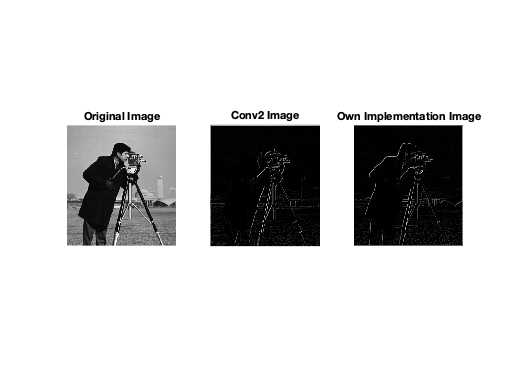

title('Own Implementation Image')

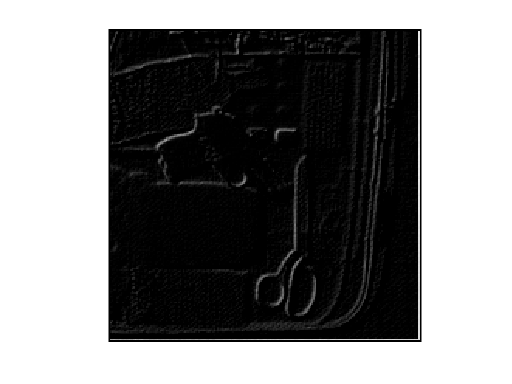


% BAG AND XRAY
img = imread('bag_xray.bmp');

% Shift and Subtract
shiftsub = [0 0 0
            0 1 0
            0 0 -1];
convimg = uint8(myconv(img, shiftsub));
figure('Name','Shift and Subtract Image','NumberTitle','off');
imshow(convimg);

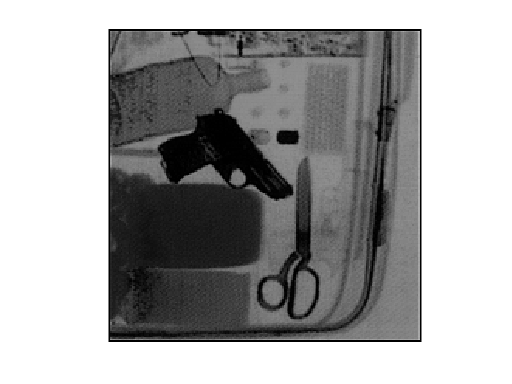


% Edge Detection K=20
k = 20;
edgedec = [-1/k -1/k -1/k
           -1/k   1  -1/k
           -1/k -1/k -1/k];
convimg = uint8(myconv(img, edgedec));
figure('Name','Edge Detection Image [k=20]','NumberTitle','off');
imshow(convimg);

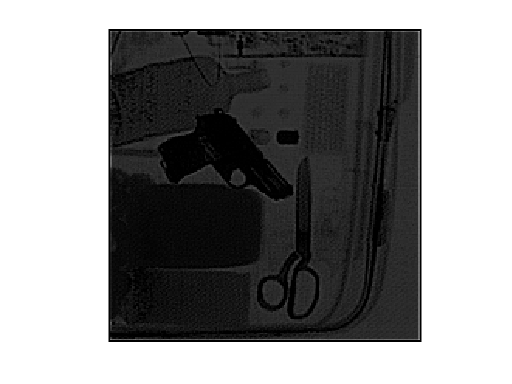


% Edge Detection K=10
k = 10;
edgedec = [-1/k -1/k -1/k
           -1/k   1  -1/k
           -1/k -1/k -1/k];
convimg = uint8(myconv(img, edgedec));
figure('Name','Edge Detection Image [k=10]','NumberTitle','off');
imshow(convimg);

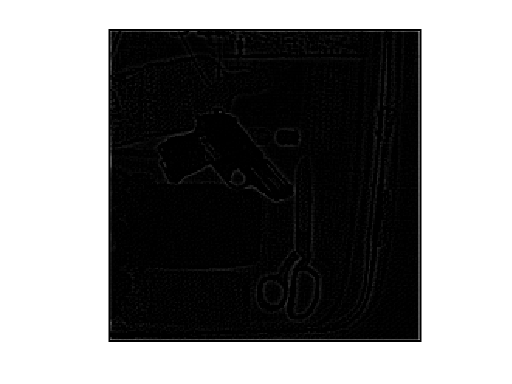


% Edge Detection K=8
k = 8;
edgedec = [-1/k -1/k -1/k
           -1/k   1  -1/k
           -1/k -1/k -1/k];
convimg = uint8(myconv(img, edgedec));
figure('Name','Edge Detection Image [k=8]','NumberTitle','off');
imshow(convimg);

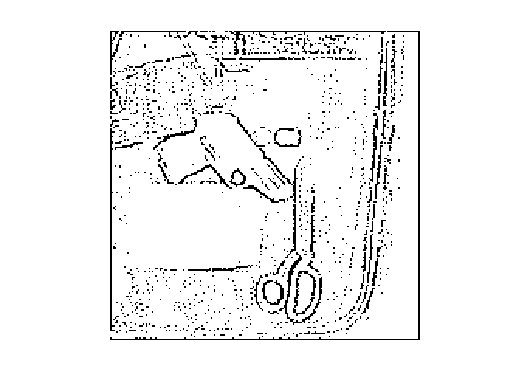


% Edge Detection with Thersholding
convimg = uint8(myconv(img, edgedec));

% Automatic Thresholding
timg = convimg;
threshold = mean(timg, 'all');
lim = 3;
diff = 100;

while diff > lim
    backg = timg(timg <= threshold);
    foreg = timg(timg > threshold);
    backgmean = mean(backg, 'all');
    foregmean = mean(foreg, 'all');
    newthreshold = mean([backgmean, foregmean]);
    diff = abs(newthreshold - threshold);
    threshold = newthreshold;
end
% Binarization
binimg = convimg;
[row, col] = size(binimg);
for r=1:row
    for c=1:col
        if binimg(r,c) > threshold
            binimg(r,c) = 0;
        else
            binimg(r,c) = 255;
        end
    end
end
figure('Name','Thresholding Image (Threshold = 10)','NumberTitle','off');
imshow(binimg);

## Illumination Flattening [Stripes]

### Notes on #2: 

Tested image operations on 3 filters: 3x3 smoothing filter, 5x5 smoothing filter, and a gaussian filter. 

Adjusted the 3x3 and 5x5 filters by both dividing them by 10 because if it was not done, the smoothed image was too bright resulting into a black/dark image when subtracted or divided the input image. 

The 3 smoothed images also represent different test cases when the operations are done, making it a good experimental setup. 

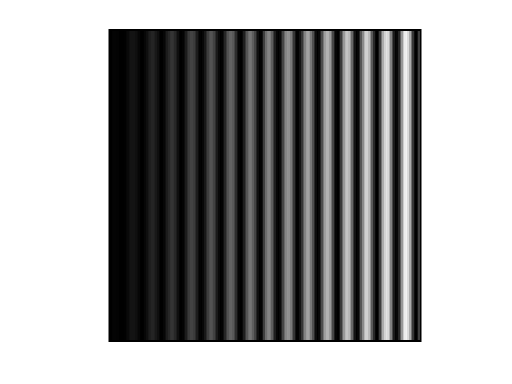


img = imread('stripes.bmp');
figure('Name','Original Image','NumberTitle','off');
imshow(img);


% Smoothing
sf3 = ones(3,3)/10;
sf5 = ones(5,5)/10;
sf3img = uint8(myconv(img, sf3));
sf5img = uint8(myconv(img, sf5));
gauimg = imgaussfilt(img, 10);

figure('Name','Smoothed Images','NumberTitle','off');
subplot(1,3,1);
imshow(sf3img);

title('3x3 Fitler Smoothing')
subplot(1,3,2);
imshow(sf5img);

title('5x5 Filter Smoothing');
subplot(1,3,3);
imshow(gauimg);

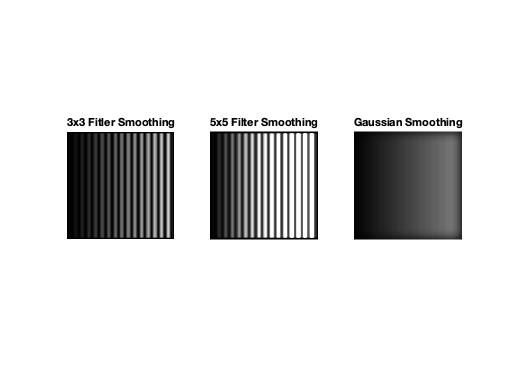

title('Gaussian Smoothing');


[row, col] = size(img);


% Subtraction
% 5x5
[sfr, sfc] = size(sf3img);
sf3pimg = sf3img(2:sfr-1, 2:sfc-1);
sub3img = zeros(row, col);
for r=1:row
    for c=1:col
        sub3img(r,c) = img(r,c) - sf3pimg(r,c);
    end
end
% 5x5
[sfr, sfc] = size(sf5img);
sf5pimg = sf5img(3:sfr-2, 3:sfc-2);
sub5img = zeros(row, col);
for r=1:row
    for c=1:col
        sub5img(r,c) = img(r,c) - sf5pimg(r,c);
    end
end
% Gaussian
subgauimg = zeros(row, col);
for r=1:row
    for c=1:col
        subgauimg(r,c) = img(r,c) - gauimg(r,c);
    end
end

figure('Name','Image Subtraction','NumberTitle','off');
subplot(1,3,1);
imshow(sub3img);

title('3x3 Subtracted')
subplot(1,3,2);
imshow(sub5img);

title('5x5 Subtracted');
subplot(1,3,3);
imshow(subgauimg);

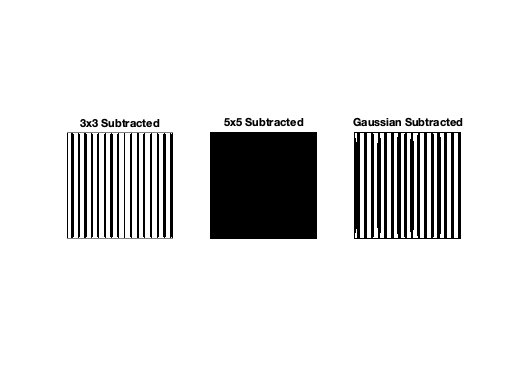

title('Gaussian Subtracted');


% Division
% 5x5
[sfr, sfc] = size(sf3img);
sf3pimg = sf3img(2:sfr-1, 2:sfc-1);
div3img = zeros(row, col);
for r=1:row
    for c=1:col
        div3img(r,c) = img(r,c) / sf3pimg(r,c);
    end
end
% 5x5
[sfr, sfc] = size(sf5img);
sf5pimg = sf5img(3:sfr-2, 3:sfc-2);
div5img = zeros(row, col);
for r=1:row
    for c=1:col
        div5img(r,c) = img(r,c) / sf5pimg(r,c);
    end
end
% Gaussian
divgauimg = zeros(row, col);
for r=1:row
    for c=1:col
        divgauimg(r,c) = img(r,c) / gauimg(r,c);
    end
end

figure('Name','Image Division','NumberTitle','off');
subplot(1,3,1);
imshow(div3img);

title('3x3 Divided')
subplot(1,3,2);
imshow(div5img);

title('5x5 Divided');
subplot(1,3,3);
imshow(divgauimg);

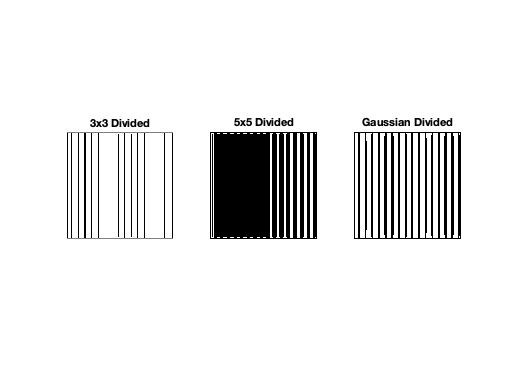

title('Gaussian Divided');

## Correlation [Washington]

### Q3: 

Question: What is your interpretation of your output in part (c)? Explain why it makes sense. 

The myconv function is essentially the correlation operator. By applying the correlation operator as a PSF/kernel filter to the input image, the matching parts are highlighted as observed. The parts that are highlighted are those with high correlations with the kernel filter, indicating a match. And high correlations are only achieved when values both from the input image and the kernel filter match each other. The problem is that when the kernel filter is too bright or close to 255. This will result into an square of white values not due to high correlation, but simply because the kernel values are too high. When the correlation operator is used (summation of products), all the image is cranked up to 255 due to the simply high values of the kernel filter, therefore, it is critical that the kernel filter is dark or has minimal values. Due to this, the found satisfactory value for the edge detection (-1/k) for the kernel filter is k = 3. 

As to why the algorithm should make sense: Due to the flipping operation of the convolution, by flipping/rotating beforehand, when the convolution operation is done, the correlation part of the convolution is the only one applied to the image. As to why use FFT, because the convulution operator is associative, computations are faster by merely multiplying the input image and the kernel filter.

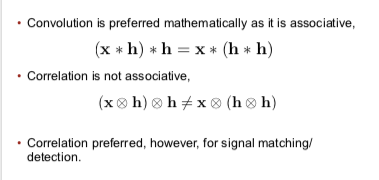


img = imread('Washington.bmp');
targetimg = imread('target_face.bmp');
figure('Name','Original Image','NumberTitle','off');
subplot(1,2,1);
imshow(img);

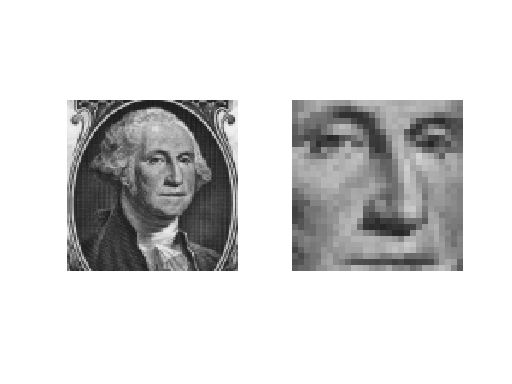

subplot(1,2,2);
imshow(targetimg);


% rotate image
rotatedimg = imrotate(targetimg,180);
% edge detected image
k = 10;
edgedec = [-1/k -1/k -1/k
           -1/k   1  -1/k
           -1/k -1/k -1/k];
filterkernel = uint8(myconv(rotatedimg, edgedec));
figure('Name','Rotated Edge Detected Image','NumberTitle','off');
subplot(1,2,1);
imshow(rotatedimg);

title('Rotated Image');
subplot(1,2,2);
imshow(filterkernel);

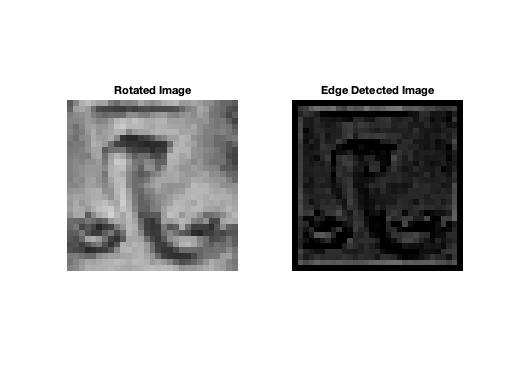

title('Edge Detected Image');


% correlation
% correlation from rotated edgedec kernel filter
% perfect k = 2.92
k = -1/3;
edgedec = [k k k
           k 1 k
           k k k];
edgedecimg2 = uint8(myconv(rotatedimg, edgedec));
corrimg = uint8(myconv(img, edgedecimg2));
% correlation from target image with edgedec
edgedecimg3 = uint8(myconv(targetimg, edgedec));
cortarimg = uint8(myconv(img, edgedecimg3));

figure('Name','Correlation Images','NumberTitle','off');
subplot(1,2,1);
imshow(corrimg);

title("Rotated Correlated Image")
subplot(1,2,2);
imshow(cortarimg);

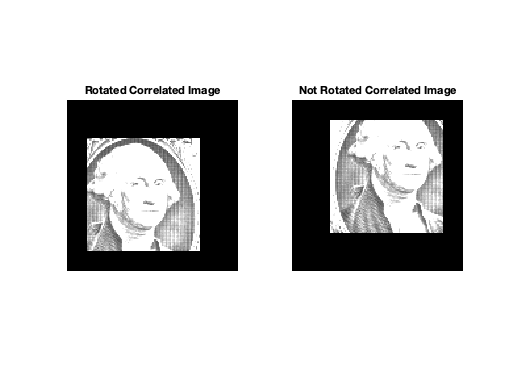

title("Not Rotated Correlated Image")


% FAILED EXPERIMENT 1 of FFT correlation
% fftimg = fft2(img);
% figure('Name','Image','NumberTitle','off');
% imshow(fftimg)
% fftfilt = fft2(edgedecimg2);
% fftfilt = padarray(fftfilt, [35,35]);
% fftfilt = fftfilt(2:length(fftfilt), 2:length(fftfilt));
% figure('Name','Image','NumberTitle','off');
% imshow(fftfilt)
% % fftmult = xcorr2(fftimg, fftfilt);
% fftmult = fftimg.*fftfilt;
% excorrimg = ifft2(fftmult);
% figure('Name','Ex Correlation Image','NumberTitle','off');
% imshow(excorrimg);
% 
% [row, col] = size(excorrimg);
% for r=1:row
%     for c=1:col
%         if excorrimg(r,c) ~= max(excorrimg,[],'all')
%             excorrimg(r,c) = 0;
%         else
%             excorrimg(r,c) = 255;
%         end
%     end
% end
% figure('Name','Ex Correlation Image','NumberTitle','off');
% imshow(excorrimg);

% 
% % FAILED EXPERIMENT 2
% or = row+fr; %-1?
% oc = col+fc;
% output = zeros(or, oc);
% 
% for r=1:or
%     for c=1:oc
%         for j=1:fr
%             for k=1:fc
%                 output(r,c) = output(r,c) + filterkernel(j,k) * img(r-k, c-j);
%             end
%         end
%     end
% end

% FAILED EXPERIMENT 3
% [row, col]  = size(img);
% [fr, fc] = size(filterkernel);
% output = uint8(myconv(padarray(edgedecimg2, [1000,1000]), img));
% figure('Name','Experiment Image','NumberTitle','off');
% imshow(output)

% FAILED EXPERIMENT 4
% max(corrimg, [],'all')
% [row, col] = size(corrimg);
% for r=1:row
%     for c=1:col
%         if corrimg(r,c) == max(corrimg,[],'all')
%             corrimg(r,c) = 255;
%         else
%             corrimg(r,c) = 0;
%         end
%     end
% end
% max(corrimg, [],'all')

## Thinning [Fingerprint]

### Q4 

Explain your algorithm briefly. 

The main algorithm for thinning the fingerprint was based on the lecture slide, binary skeletonization. 

Brief Algorithm/Rules 

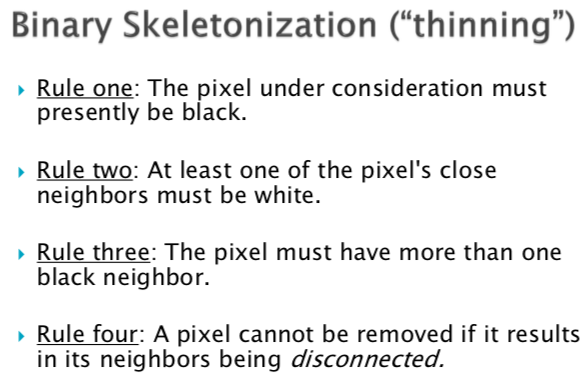

Instant Thinning Algorithm: 

- Slide 3x3 window 

- If the center of the 3x3 window satisfies all the rules, set the center pixel value to white (255). 

Following the above rules, and thinning/setting that pixel to 255 white instantly results into the image labeled as “Thinned Instantly”. As can be observed, the dark lines towards the lower right disappears from the image. The possible explanation for this is that the window that thins the image starts from the upper left corner. As the the window moves right and downwards, the 3x3 small window erases all the dark outlines that are actually necessary but is not observed in the 3x3 window. Because that pixel in the 3x3 window is not observed, rule four: “a pixel cannot be removed if it results in its neighbors being disconnected.” is violated. Therefore, dark outlines in the lower right disappeared.  

To counteract this, we experimented on delaying the thinning with the following algorithm. 

Delayed Thinning Algorithm 

- Slide 3x3 window 

- If the center of the 3x3 window satisfies all the rules, mark the center pixel value to be changed, but leave it for this pass/iteration 

- When all the pixels have been passed through/marked, the pixels that were marked to be changed (those that satisfied all the above rules), will be changed and set to white (255). 

This is observed in the “Thinned with Delay” image. The problem in this image is that thick dark outlines remain. Because the thinning is delayed, when the window reaches a thick outline, its 3x3 frame is filled with black (0) values which violates rule two: “At least one of the pixel's close neighbors must be white”. This leads to those dark outlines being ignored as target for thinning. There’s also another problem which lies in the upper left of the image. The upper left dark outlines disappeared. A possible explanation for this is because the upper left outlines were thin. Because they were thin or were connected by 1 (diagonal) pixel, when the first pass was done, most of the upper left outlines were marked to be whitened, resulting to the current image. 

The two images, "thinned instantly" and "thinned with delay" seems to have opposite problems and results, so it was experimented to combine the two resulting images. This image is then labeled as “Thinning Instant + Delay” image. This is then contrasted to the original image. Even the resulting image is somewhat better, the main possible improvement that should be focused upon is the thinning of the thick dark outlines that is derived from the “thinned with delay” algorithm. Possible conclusions that can be made: 1) thinning should not be done instantly, 2) the sliding window should possibly be bigger, 3) multiple passes on thinning should be done, to reduce the thick outlines and as to not erase thin outlines. 


origimg = imread('fingerprint.bmp');

% hyperparameters
% 5x5, pd = 2
% 3x3, pd = 1

a = 3; %window length
hp = 1; %padding
origimg = padarray(origimg, [hp,hp], 1);
pr=hp;
pc=hp;

[row, col] = size(origimg);

% Change instantly
img=origimg;
for r=1+pr:row-pr
        for c=1+pr:col-pr
    %         center = r,c
            area = img(r-pr:r+pr, c-pc:c+pc);
            area(a-hp,a-hp) = 100;

    %         if current pixel is black
            if img(r,c) == 0

    %             if at least 1 neighbor is white
                if max(area,[],'all') == 255

    %                 if black neighbor > 1
                    bcount = 0;
                    nb = false;
                    for i=1:a
                        for j=1:a
                            if area(i,j) == 0
                                bcount = bcount+1;
    %                             are there neighboring blacks?

    %                             down
                                if i+1 <= a
                                if area(i+1, j) == 0
                                    nb = true;
                                end
                                end

    %                             up
                                if i-1 >= 1
                                if area(i-1, j) == 0
                                    nb = true;
                                end
                                end

    %                             right
                                if j+1 <= a
                                if area(i, j+1) == 0
                                    nb = true;
                                end
                                end

    %                             left
                                if j-1 >= 1
                                if area(i, j-1) == 0
                                    nb = true;
                                end
                                end

    %                             up left
                                if i-1 >= 1 & j-1 >=1
                                if area(i-1, j-1) == 0
                                    nb = true;
                                end
                                end

    %                             up right
                                if i-1 >= 1 & j+1 <= a
                                if area(i-1, j+1) == 0
                                    nb = true;
                                end
                                end

    %                             down left
                                if i+1 <= a & j-1 >= 1
                                if area(i+1, j-1) == 0
                                    nb = true;
                                end
                                end

    %                             down right
                                if i+1 <= a & j+1 <= a
                                if area(i+1, j+1) == 0
                                    nb = true;
                                end
                                end
                            end
                        end
                    end
                    if bcount > 1 & nb == true
                        img(r,c) = 255;
                    end
                end
            end
        end
end
instant = img;
figure('Name','Thinned Instantly','NumberTitle','off');
imshow(instant);

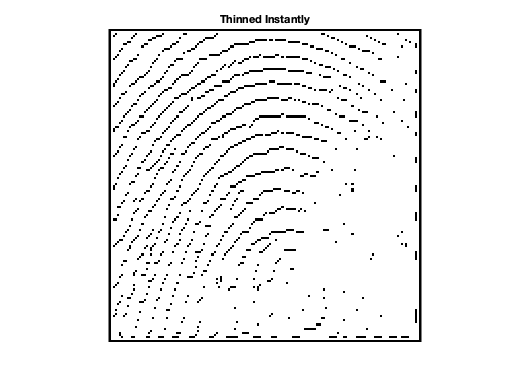

title('Thinned Instantly'); 


% Change with delay
img = origimg;
change = true;
for ctr=1:1
    imgchange = zeros(row, col);
    change = false;

    for r=1+pr:row-pr
        for c=1+pr:col-pr
    %         center = r,c
            area = img(r-pr:r+pr, c-pc:c+pc);
            area(a-hp,a-hp) = 100;

    %         if current pixel is black
            if img(r,c) == 0

    %             if at least 1 neighbor is white
                if max(area,[],'all') == 255

    %                 if black neighbor > 1
                    bcount = 0;
                    nb = false;
                    for i=1:a
                        for j=1:a
                            if area(i,j) == 0
                                bcount = bcount+1;
    %                             are there neighboring blacks?

    %                             down
                                if i+1 <= a
                                if area(i+1, j) == 0
                                    nb = true;
                                end
                                end

    %                             up
                                if i-1 >= 1
                                if area(i-1, j) == 0
                                    nb = true;
                                end
                                end

    %                             right
                                if j+1 <= a
                                if area(i, j+1) == 0
                                    nb = true;
                                end
                                end

    %                             left
                                if j-1 >= 1
                                if area(i, j-1) == 0
                                    nb = true;
                                end
                                end

    %                             up left
                                if i-1 >= 1 & j-1 >=1
                                if area(i-1, j-1) == 0
                                    nb = true;
                                end
                                end

    %                             up right
                                if i-1 >= 1 & j+1 <= a
                                if area(i-1, j+1) == 0
                                    nb = true;
                                end
                                end

    %                             down left
                                if i+1 <= a & j-1 >= 1
                                if area(i+1, j-1) == 0
                                    nb = true;
                                end
                                end

    %                             down right
                                if i+1 <= a & j+1 <= a
                                if area(i+1, j+1) == 0
                                    nb = true;
                                end
                                end
                            end
                        end
                    end
                    if bcount > 1 & nb == true
                        imgchange(r,c) = true;
                    end
                end
            end
        end
    end
    
    for r=1:row
        for c=1:col
            if imgchange(r,c)
                img(r,c) = 255;
%                 change = true;
            end
        end
    end
end
delay = img;
figure('Name','Thinned with Delay','NumberTitle','off');
imshow(delay);

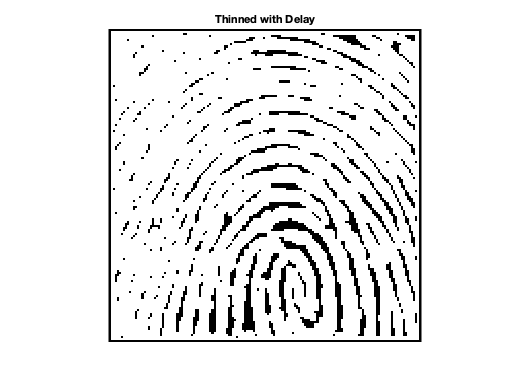

title('Thinned with Delay'); 


figure('Name','Fingerpint Thinning','NumberTitle','off');
together = min(instant, delay);
subplot(1,2,1);
imshow(origimg);

title('Original');
subplot(1,2,2);
imshow(together);

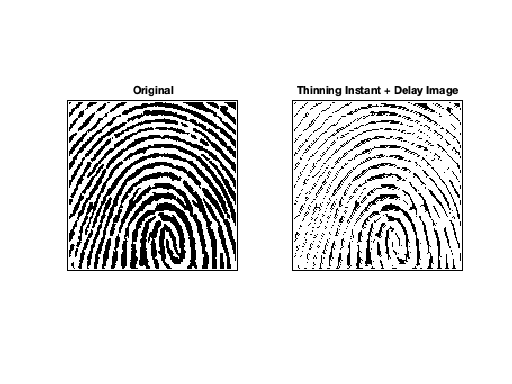

title('Thinning Instant + Delay Image')

## Functions

function convimg = myconv(img, fil)
[row, col] = size(img);

% newimg = zeros(row+2, col+2);
% for r=1:row
%     for c=1:col
%         newimg(r+1,c+1) = img(r,c);
%     end
% end

filen = length(fil);
p = double(idivide(int32(filen), int32(2), 'floor'));
fil = double(fil);
% if filen == 3
%     p = 1;
% end
% if filen == 5
%     p = 2;
% end
% if fillen == 27
%     p = 13;

newimg = double(padarray(img, [p,p]));
[nr, nc] = size(newimg);
convimg = zeros(nr, nc);
for r=1+p:row+p
    for c=1+p:col+p
        tobeconv = newimg(r-p:r+p, c-p:c+p);
        convimg(r,c) = sum(tobeconv.*fil, 'all');
    end
end

convimg = uint8(convimg);
end
